**Data Generation for Graph Neural Networks**

This is a simple test (possibly 2D steady state) for creating datasets for training a Graph Neural Networks with Finite Element Nodes. Requires Matlab PDE toolbox to run. 

clear;
close all;

The GNNs have input as a graph and output as temperature at all nodes. Note that GNNs can work with varying "sizes" of graphs - i.e., each "graph datapoint" can have different number of nodes and edges. 

The **current idea**

Nodes of Graph - are exactly nodes of Finite Element Method. 

Edges of Graph - Connect only with "neighboring" nodes? - With feature as the distance? 

                            More *correct *way is possibly to say each "element" is connected. 

**Ideally - **Generating data with multiple geometries - using the "descg" (alternate way is to use .stl) that save inputs. 

%Rectangle 
label = "geom1";
width = 3; 
height = 2;
gdm = [3 4 0 width width 0 0 0 height height]'; %Describes a geometry

From Matlab Documentation - https://www.mathworks.com/help/pde/ug/decsg.html

*Geometry description matrix, specified as a matrix of double-precision numbers. The number of columns corresponds to the number of shapes used to construct the geometry. Each column in the geometry description matrix corresponds to a shape in the CSG model. The model supports four types of shapes:*

- *For a circle, the first row contains *`1`*. The second and third rows contain the x- and y-coordinates of the center. The fourth row contains the radius of the circle. The radius must be a positive value.*

- *For a polygon, the first row contains *`2`*. The second row contains n, which is the number of line segments in the boundary of the polygon. The next n rows contain the x-coordinates of the starting points of the edges, and the n rows after that contain the y-coordinates of the starting points of the edges.*

- *For a rectangle, the first row contains *`3`*, and the second row contains *`4`*. The next four rows contain the x-coordinates of the starting points of the edges, and the four rows after that contain the y-coordinates of the starting points of the edges.*

- *For an ellipse, the first row contains *`4`*. The second and third rows contain the x- and y-coordinates of the center. The fourth and fifth rows contain positive values, specifying the lengths of the semiaxes of the ellipse. The sixth row contains the rotational angle of the ellipse, measured in radians.*

*All shapes in a geometry description matrix have the same number of rows. Elements of the matrix that are not required to encode information about the corresponding shapes must be set to zero.*

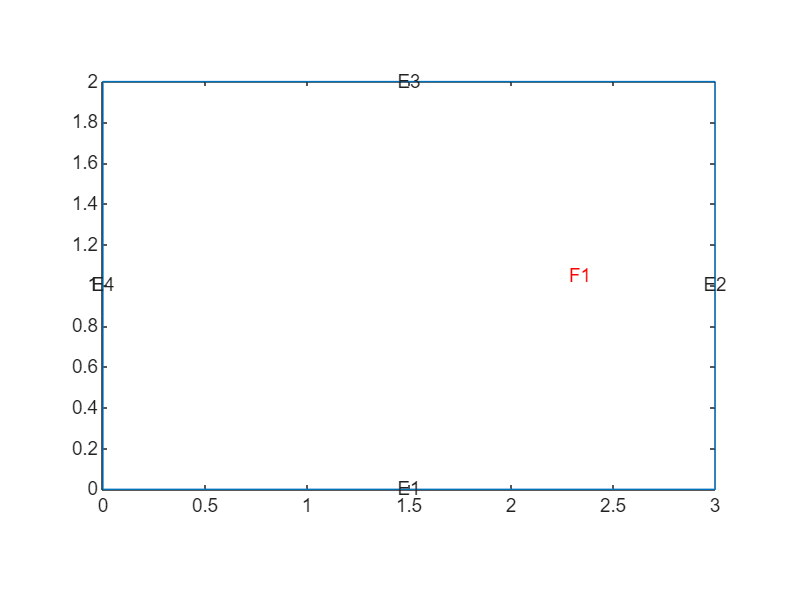

k = 0.001;
Q = 1;
ta = 300;
dl = decsg(gdm, 'S1', ('S1')');
pdegplot(dl,"EdgeLabels","on","FaceLabels","on")

% saveas(gcf,label+"outline.png")

Considering a single physics system 


$$$k(\frac{\partial^2 T}{\partial x^2} + \frac{\partial^2 T}{\partial y^2}) + Q = 0$$$


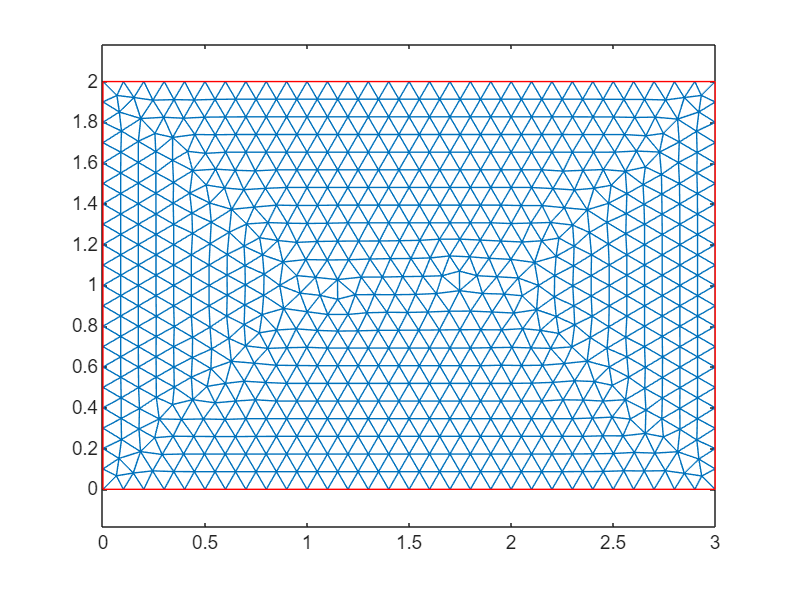

numberOfPDE = 1;
model = createpde(numberOfPDE);

geometryFromEdges(model,dl);

hmax = 0.1; % element size
msh = generateMesh(model,'Hmax',hmax);
figure
pdeplot(model)

Specifying PDE coefficients and Boundaries

I will choose mixed boudaries - Dirchilet and Neumann

specifyCoefficients(model,'m',0,'d',0,'c',k,'a',0,'f',Q);

applyBoundaryCondition(model,'dirichlet',"Edge",[1,2,3,4],"u",ta); %Modify for Every geometry

Solving next.. - also output the computational time. 

tic
R = solvepde(model);
toc

Elapsed time is 0.018217 seconds.


Extracting and plotting.. 

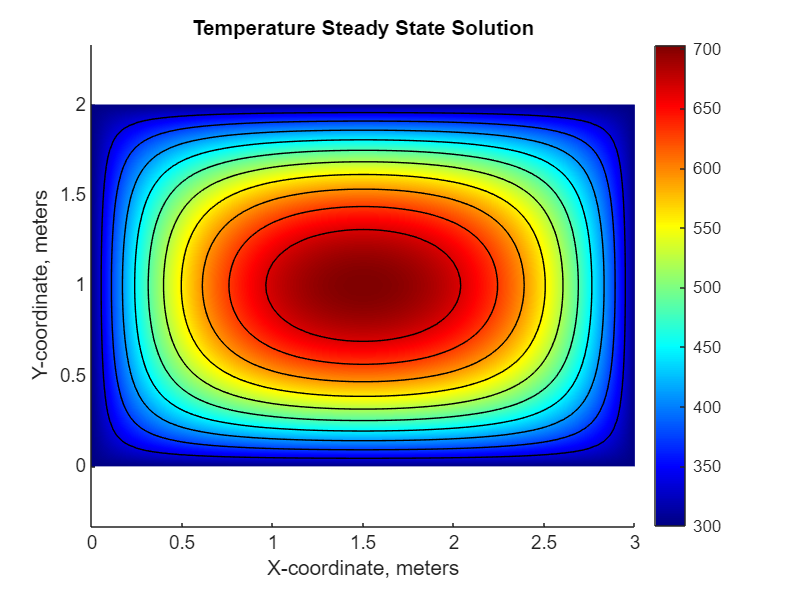

u = R.NodalSolution;
figure; 
pdeplot(model,"XYData",u,"Contour","on","ColorMap","jet");
title("Temperature Steady State Solution")
xlabel("X-coordinate, meters")
ylabel("Y-coordinate, meters")
axis equal

Getting the "edges" to form the graph for GNNs - 

using `findNodes` - https://www.mathworks.com/help/pde/ug/pde.femesh.findnodes.html

boundaryNodes = findNodes(msh, "region", "Edge",1:4)

boundaryNodes =            1         920          24        1293          25        1000          26        1318          27         944          28        1302          29         917          30         950          31        1047          32        1068          33         765          34        1192          35        1126          36         904          37        1271          38         885          39        1225          40        1314          41         884          42         880          43         875          44        1172          45         864          46         861          47        1149


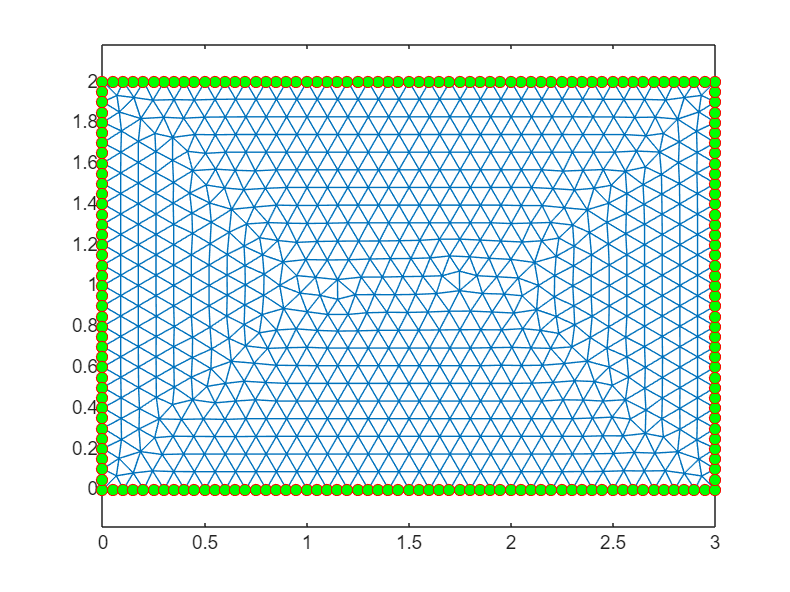

figure
pdemesh(model)
hold on
plot(msh.Nodes(1,boundaryNodes),msh.Nodes(2,boundaryNodes),"or","MarkerFaceColor","g")